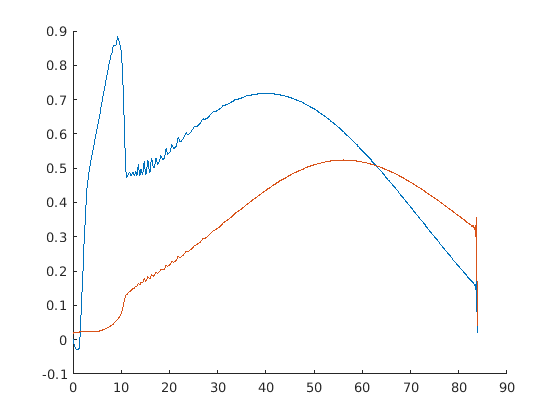

csv = csvread('1.csv');
a = csv(:,1);
cl = csv(:,2);
cd = csv(:,3);
cdp = csv(:,4);
cm = csv(:,5);
topxtr = csv(:,6);
botxtr = csv(:,7);
topitr = csv(:,8);
botitr = csv(:,9);

hold off;
%plot(a, cl);
hold on;
%plot(a, cd);

[cl_s, a_cl_s] = resample(cl, a, 10, 'spline');
plot(a_cl_s, cl_s);
[cd_s, a_cd_s] = resample(cd, a, 10, 'spline');
plot(a_cd_s, cd_s);
%scatter(a, cl);
%scatter(a, cd);
%{
bwlpf = designfilt('lowpassiir', 'PassbandFrequency', 0.1, 'StopbandFrequency', 0.2, ...
'PassbandRipple', 0.5, 'StopbandAttenuation', 65, 'DesignMethod', 'butter', ...
'SampleRate', 1/(a_cl_s(2)-a_cl_s(1)) ...
);
%}


pass = 0.12;
stop = 0.29;
ripple = 0.5;
atten = 70;

firlpf = designfilt('lowpassfir', 'PassbandFrequency', pass, 'StopbandFrequency', stop, ...
'PassbandRipple', ripple, 'StopbandAttenuation', atten, 'DesignMethod', 'equiripple', ...
'SampleRate', 1/(a_cl_s(2)-a_cl_s(1)) ...
);

[A, B, C, D]=ss(firlpf);
firlpf_ss = ss(A, B, C, D, 1/firlpf.SampleRate);
%[A, B, C, D] = ss(bwlpf);
%bwlpf_ss = ss(A, B, C, D, 1/firlpf.SampleRate);

%firlpf.freqz;
%bwlpf.freqz;

hold off;

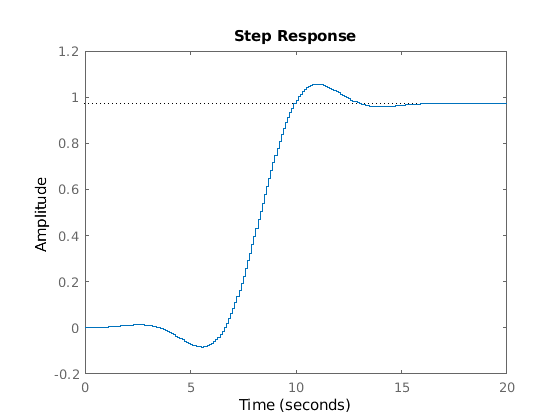

step(firlpf_ss);
%hold on;
%step(bwlpf_ss);
%legend('fir', 'bw');

%hold off;

[fir_out_cl, fir_out_cl_a] = lsim(firlpf_ss, cl_s, a_cl_s);
[fir_out_cd, fir_out_cd_a] = lsim(firlpf_ss, cd_s, a_cd_s);
%delay = mean(grpdelay(firlpf))

%{
fir_out_cl_a = fir_out_cl_a(1:end-delay);
fir_out_cl = fir_out_cl(1:end-delay);
fir_out_cd_a = fir_out_cd_a(1:end-delay);
fir_out_cd = fir_out_cd(1:end-delay);
%}

a_cd_s = a_cd_s(1:end-delay);
a_cl_s = a_cl_s(1:end-delay);
cd_s = cd_s(1:end-delay);
cl_s = cl_s(1:end-delay);

fir_out_cl(1:delay) = [];
fir_out_cd(1:delay) = [];
fir_out_cl_a(1:delay) = [];
fir_out_cd_a(1:delay) = [];
%{
fir_out_cl = fir_out_cl(delay:end);
fir_out_cd = fir_out_cd(delay:end);
fir_out_cl_a = fir_out_cl_a(delay:end);
fir_out_cd_a = fir_out_cd_a(delay:end);
%}

fir_out_cl_a = fir_out_cl_a - fir_out_cl_a(1);
fir_out_cd_a = fir_out_cd_a - fir_out_cd_a(1);


hold off;

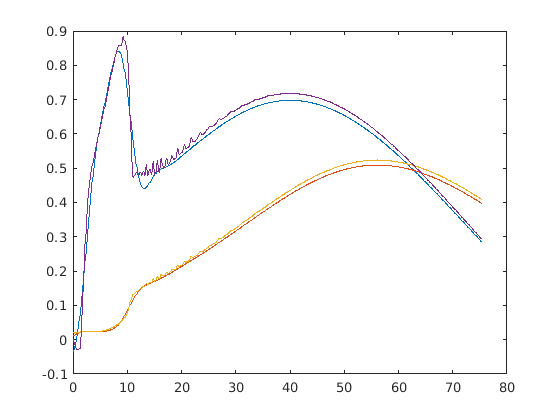

plot(fir_out_cl_a, fir_out_cl);
hold on;
plot(fir_out_cd_a, fir_out_cd);
plot(a_cd_s, cd_s);
plot(a_cl_s, cl_s);


%alpha    CL        CD       CDp       CM     Top_Xtr  Bot_Xtr  Top_Itr  Bot_Itr